# Classification Models

Load the pump features from `pumpFeatures.`

T = readtable("./data/pumpFeatures.csv");

Partition into training and testing

rng(0)
cv = cvpartition(size(T, 1), "HoldOut", 0.3);
dataTrain = T(cv.training, :);
dataTest = T(cv.test, :)

dataTest = 300×85 table
    wMotor_mean    wMotor_std    wMotor_fftPeakIdx    wMotor_skewness    wMotor_kurtosis    wMotor_peak2peak    wMotor_peak2rms    wMotor_rms    wMotor_mad    wMotor_csRange    wMotor_pLow    wMotor_pMid    wMotor_pHigh    wMotor_pKur    iMotor_mean    iMotor_std    iMotor_fftPeakIdx    iMotor_skewness    iMotor_kurtosis    iMotor_peak2peak    iMotor_peak2rms    iMotor_rms    iMotor_mad    iMotor_csRange    iMotor_pLow    iMotor_pMid    iMotor_pHigh    iMotor_pKur    qIn_mean   

## Binary decision tree for multiclass classification

mdl = fitctree(dataTrain, "faultCode");
preds = predict(mdl, dataTest);
err = loss(mdl, dataTest)

err = 0.1172

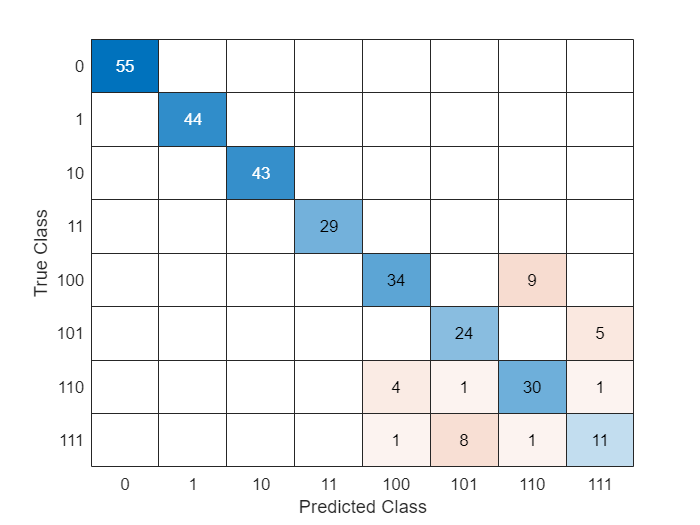

confusionchart(dataTest.faultCode, preds)

## Multiclass naive Bayes

mdl = fitcnb(dataTrain, "faultCode");
preds = predict(mdl, dataTest);
err = loss(mdl, dataTest)

err = 0.1665

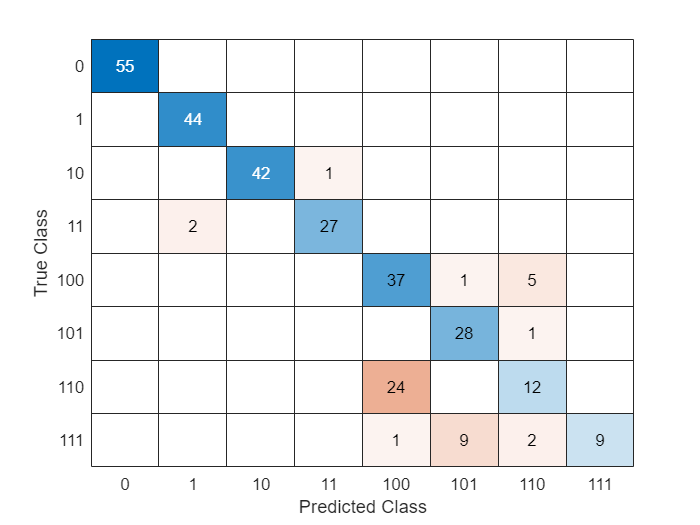

confusionchart(dataTest.faultCode, preds)

## Discriminant analysis classifier

mdl = fitcdiscr(dataTrain, "faultCode");
preds = predict(mdl, dataTest);
err = loss(mdl, dataTest)

err = 0.1212

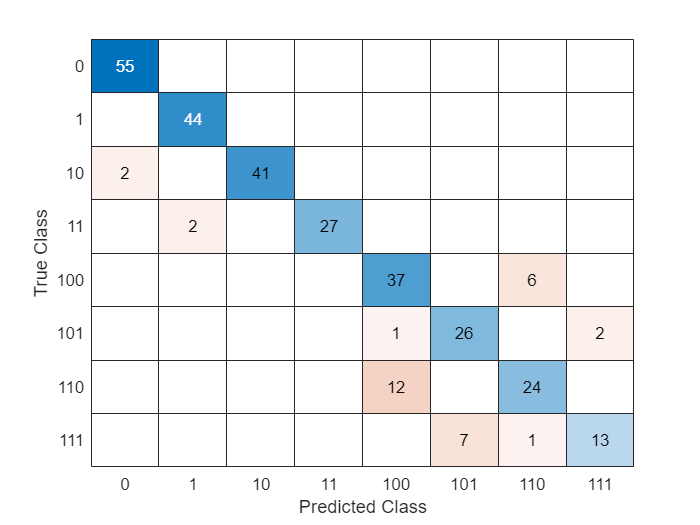

confusionchart(dataTest.faultCode, preds)

## Multiclass models for support vector machines

mdl = fitcecoc(dataTrain, "faultCode");
preds = predict(mdl, dataTest);
err = loss(mdl, dataTest)

err = 0.3767

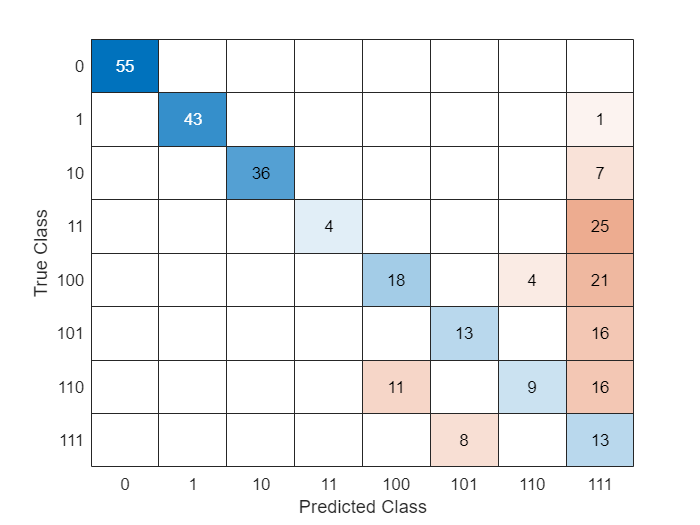

confusionchart(dataTest.faultCode, preds)

## k-nearest neighbor classifier

mdl = fitcknn(dataTrain, "faultCode");
preds = predict(mdl, dataTest);
err = loss(mdl, dataTest)

err = 0.1116

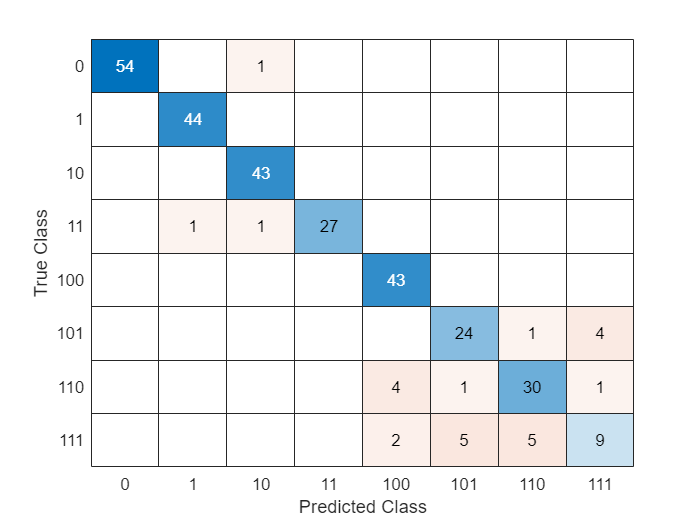

confusionchart(dataTest.faultCode, preds)